# Tune Closed-Loop Velocity Controller Parameters

## Description

Goal of this exercise is to tune controller gains of Velocity Controller and Current Controller to meet certain performance requirements while respecting hardware limits (20amp Current Limit of Inverter). 

Below are stated requirements from Functional Requirement Document. 

- The motor speed shall settle within 0.2 seconds of step change in commanded speed. 

- Settling error (Commanded speed - Motor Speed) shall be with the velocity measurement noise (+/- 1rad/sec).

To tune the controller, we will first use desktop simulation (FieldOrientedController_MIL.slx) to arrive at reasonable values for controller gains. 

Then to fine tune the overall performance and get the most out given system, we will use [Simulink Design Optimization](https://www.mathworks.com/products/sl-design-optimization.html#response) to tune multiple gains (see the list below) at the same time while respecting limits of hardware (current limits of inverter) and disturbances (change in load torque).

- paramCurrentControlP

- paramCurrentControlI

- paramVelociyControlP

- paramVelocityControlI  

#### Required Tools

- Simulink Design Optimization

- Optimization Toolbox (Pre-requisite for Simulink Design Optimization)

## Simulate and Plot Initial Design 

#### Open Desktop Simulink Model

mdl = 'FieldOrientedController_MIL';
open_system(mdl);
switchConfig('MIL');
% Select Configuration which is not a Configuration Reference. 
% Simulink Design Optimization does not work with Configuration Reference
setActiveConfigSet(mdl,'Sim1'); 

#### Select Test Case from Signal Editor Group

set_param([mdl,'/enManualTestInputs'],'Value','0'); % Select SignalEditor_Experiments as Test Inputs 
set_param([mdl,'/SignalEditor_Experiments'], ...
    'ActiveScenario','Step_with_Torque_Disturbance_Rejection'); % Select Experiment

#### Start Simulation

set_param(mdl,'SimulationCommand','Start','StopTime','5');

#### Plot Results

experimentRun = Simulink.sdi.Run.getLatest;
experimentRun.Name = ['BeforeControllerTuning - ' char(experimentRun.DateCreated)];
rotVel = getSignalsByName(experimentRun,'rotorVelocity');
phCur = getSignalsByName(experimentRun,'phaseCurrent');
Simulink.sdi.setSubPlotLayout(2,1);
plotOnSubPlot(rotVel,1,1,true);
plotOnSubPlot(phCur.Children(1),2,1,true);
plotOnSubPlot(phCur.Children(2),2,1,true);
%sigExp.Checked = true; % Mark Signal for Plotting
Simulink.sdi.view;% Open Simulation Data Inspector UI

## Open Simulink Design Optimization Test Bench

Load Simulink Design Optimization Session

load('FieldOrientedController_sdosession.mat');

Open Simulink Design Optimization

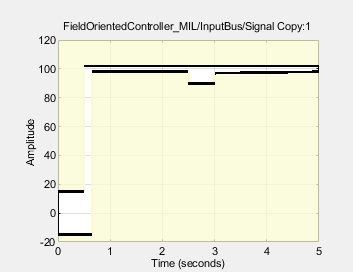

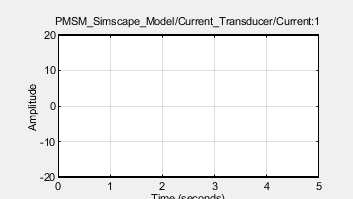

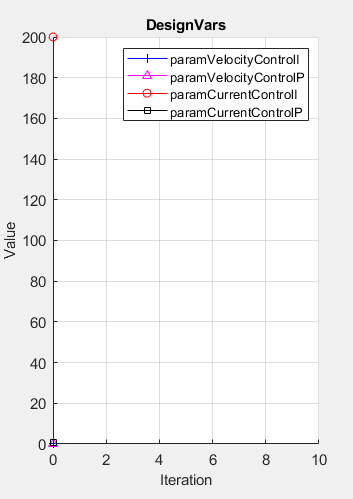

sdotool(SDOSessionData);

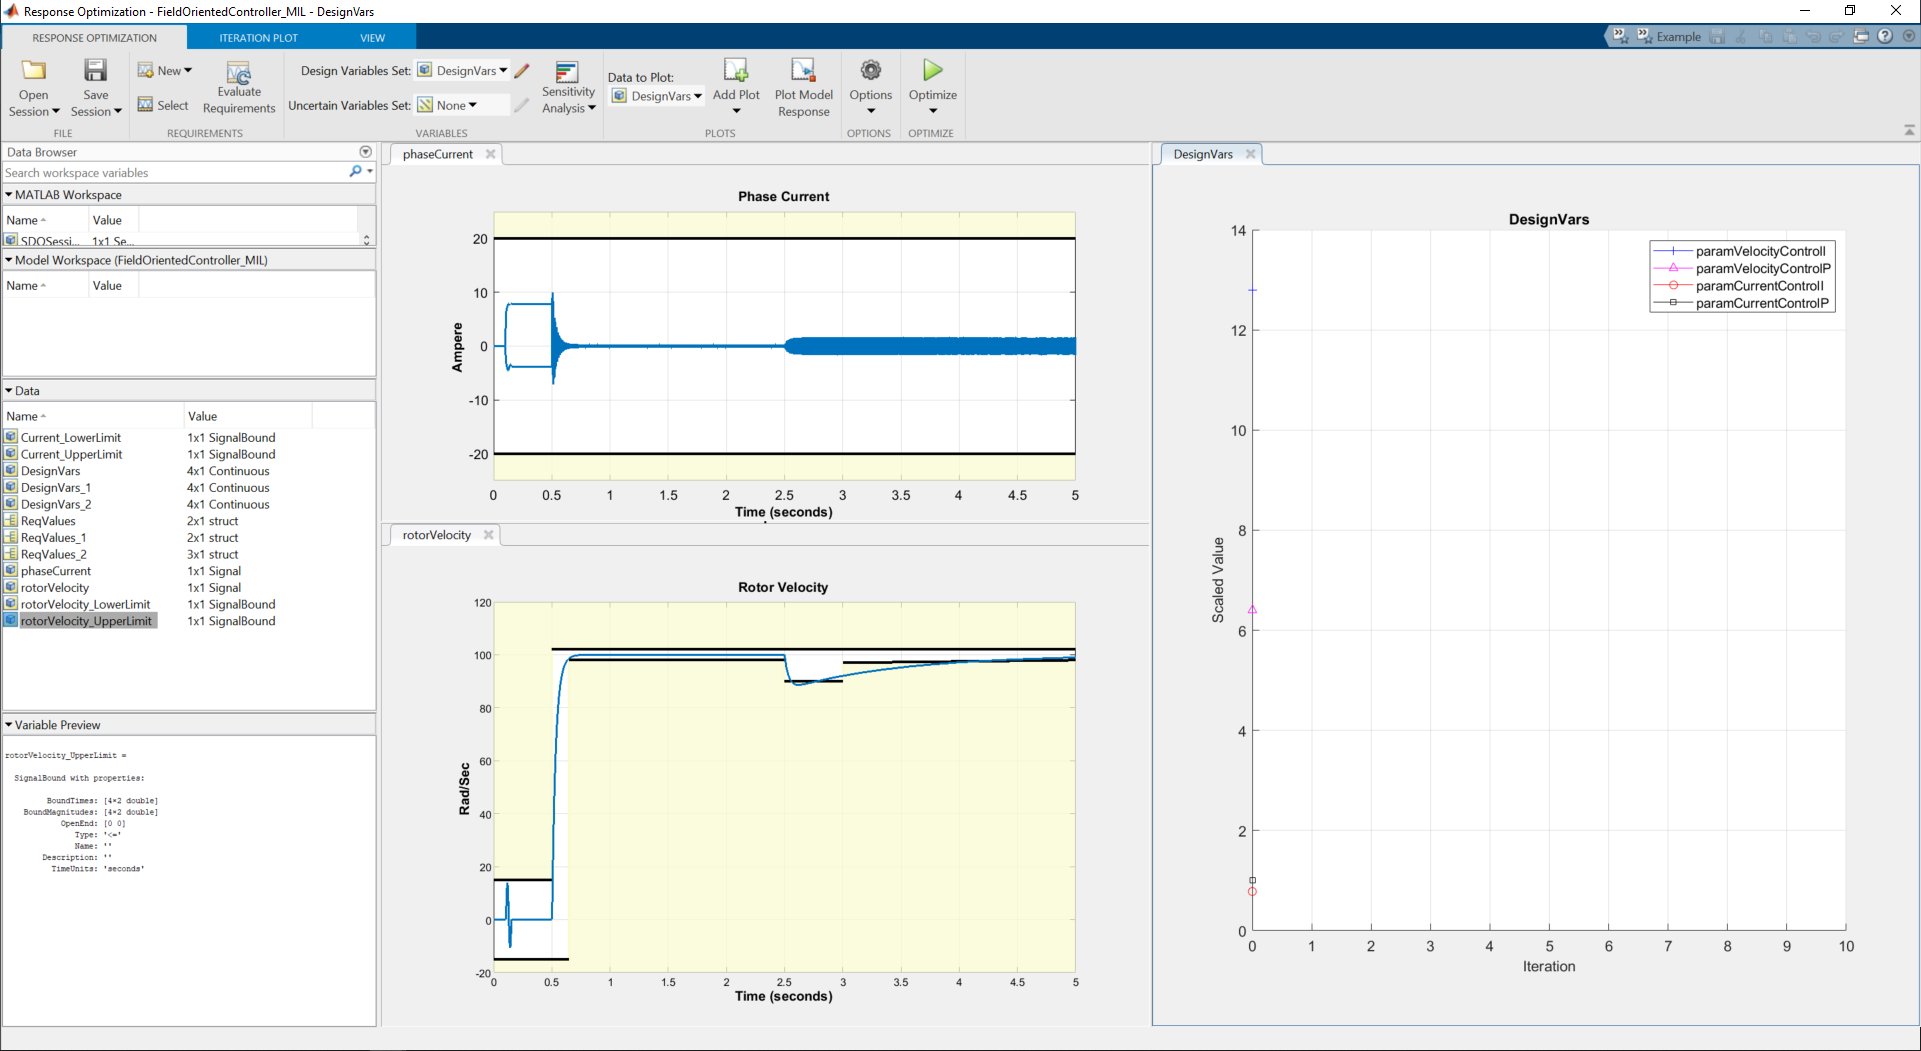

Click on **Plot Motor Response** to check if controller response fall into the limits (requirements).  

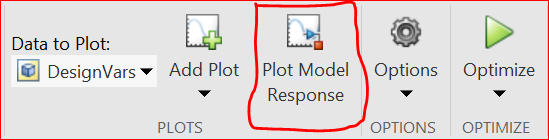

Next, Click on **Optimize** button to start optimization to find values of controller parameters that meet limits (requirements).

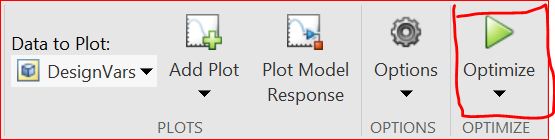

## Watch Simulink Design Optimization Video

Open Pre-Recorded Video of Simulink Design Optimization

winopen('FocResponseOptimization.mp4');

## Inspect Final Results in Simulation

open_system(mdl);

#### Set Gains from Simulink Design Optimization

ddCntrl = Simulink.data.dictionary.open('SGKitControllerData.sldd');
setValue(getEntry(ddCntrl.getSection('Design Data'),'paramVelocityControlP'),0.0545);
setValue(getEntry(ddCntrl.getSection('Design Data'),'paramVelocityControlI'),0.146);
setValue(getEntry(ddCntrl.getSection('Design Data'),'paramCurrentControlP'),2.0716);
setValue(getEntry(ddCntrl.getSection('Design Data'),'paramCurrentControlI'),56.061);

#### Start Simulation with Optimized Gains

sim(mdl,'StopTime','5');

#### Plot Results

experimentRun = Simulink.sdi.Run.getLatest;
experimentRun.Name = ['AfterControllerTuning - ' char(experimentRun.DateCreated)];
rotVel = getSignalsByName(experimentRun,'rotorVelocity');
phCur = getSignalsByName(experimentRun,'phaseCurrent');
Simulink.sdi.setSubPlotLayout(2,1);
plotOnSubPlot(rotVel,1,1,true);
plotOnSubPlot(phCur.Children(1),2,1,true);
plotOnSubPlot(phCur.Children(2),2,1,true);
Simulink.sdi.view;% Open Simulation Data Inspector UI

#### Reset Configuration

switchConfig('MIL');    

## Test Controller Performance with Hardware in Real-Time

#### Open Test Bench and Setup Coast Down Experiment

mdl = 'FieldOrientedController_RCP';
open_system(mdl);
switchConfig('RCP');
%switchMotorKit('SG_Inverter_RCP_Kit');

Select Signal Editor Experiement 

set_param([mdl,'/enManualTestInputs'],'Value','0'); % Select SignalEditor_Experiments as Test Inputs 
set_param([mdl,'/SignalEditor_Experiments'], ...
    'ActiveScenario','Step_with_Torque_Disturbance_Rejection'); % Select Experiment

#### Build Model for Speedgoat Real-Time Target

rtwbuild(mdl); % Build Model

#### Run Experiment

tg = slrt;
load(tg,mdl);
tg.StopTime = 5;
tg.start; pause(5);

#### Plot Results

experimentRun = Simulink.sdi.Run.getLatest;
experimentRun.Name = ['Experiment Results - ' char(experimentRun.DateCreated)];
rotVel = getSignalsByName(experimentRun,'rotorVelocity');
phCur = getSignalsByName(experimentRun,'phaseCurrent');
Simulink.sdi.setSubPlotLayout(2,1);
plotOnSubPlot(rotVel,1,1,true);
plotOnSubPlot(phCur.Children(1),2,1,true);
plotOnSubPlot(phCur.Children(2),2,1,true);
Simulink.sdi.view;% Open Simulation Data Inspector UI

## Restore Data Dictionary

ddCntrl.discardChanges;
clear ddCntrl mdl rotVel phCur experimentRun